# **Trayectorias**

Se comienza por establecer los arcos que establecen el rango.

thetaMin = linspace(0,360,100);
rMin = 100;
xRanMin = -rMin*cosd(thetaMin);
yRanMin = rMin*sind(thetaMin);
rMax = 200;
thetaMax = linspace(0,360,100);
xRanMax = -rMax*cosd(thetaMax);
yRanMax = rMax*sind(thetaMax);

## Trayectorias

### Triángulo

xiT = 100;
yiT = -100;
Len = 50;
[xT, yT] = triEq(xiT,yiT,Len);

### Círculo

xCC = 100;
yCC = 100;
R = 30;
[xC, yC] = circleDiscrete(xCC,yCC,R,8);

## Letras

s = 20;
xF = 100;
yF = s+10;
[xL, yL] = FINLetter(xF,yF,20);

## Líneas Paralelas

Largo = s*3 + 20;
[xP, yP] = Parallel(xF+10+2*s,yF,s,Largo);

## Puntos

[xDots, yDots] = Dots(10,110,15,5)

xDots =     10    25    40    55    70


yDots =    110   125   140   155   170


## Gráfica

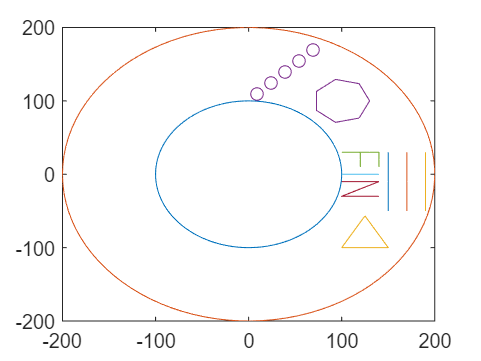

plot(xRanMin,yRanMin)
hold on
plot(xRanMax,yRanMax)
plot(xT,yT)
plot(xC, yC)
plot(xL(1:15),yL(1:15))
plot(xL(16:18),yL(16:18))
plot(xL(19:27),yL(19:27))
plot(xP(1:3),yP(1:3))
plot(xP(4:6),yP(4:6))
plot(xP(7:9),yP(7:9))
plot(xDots,yDots,'o')